## **Radar Target Generation and Detection Project**

Project 2 of Udacity's Sensor Fusion nanodegree - **Radar Target Generation and Detection.**

### Project Overview

- Configure the FMCW waveform based on the system requirements.

- Define the range and velocity of target and simulate its displacement.

- For the same simulation loop process the transmit and receive signal to determine the beat signal

- Perform Range FFT on the received signal to determine the Range

- Towards the end, perform the CFAR processing on the output of 2nd FFT to display the target.

### Configure the system parameters

clear all
clc;
%% Radar Specifications 
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%speed of light = 3e8
%% User Defined Range and Velocity of target
% *%TODO* :
% define the target's initial position and velocity. Note : Velocity
% remains contant
Range_target_init = 120; %%m    %initial range of target
Velocity_target = -5; %%m/s     %relative speed, approaching vehicle

%% FMCW Waveform Generation

% *%TODO* :
%Design the FMCW waveform by giving the specs of each of its parameters.
% Calculate the Bandwidth (B), Chirp Time (Tchirp) and Slope (slope) of the FMCW
% chirp using the requirements above.


%Operating carrier frequency of Radar 
fc = 77e9;              %carrier freq
c = 3e8;                %speed of light = 3e8
d_res = 1;              %Range Resolution = 1 m
B = c/(2*d_res);        %Bandwidth (B)

Rmax = 200;             %Max Range = 200m
Tchirp = 5.5*2*Rmax/c;  %Chirp Time (Tchirp)

slope =  B/Tchirp;      %Slope (slope)
                                                          
%The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
%for Doppler Estimation. 
Nd=128;                   % #of doppler cells OR #of sent periods % number of chirps

%The number of samples on each chirp. 
Nr=1024;                  %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each
% chirp
t=linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples


%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx=zeros(1,length(t)); %transmitted signal
Rx=zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal

%Similar vectors for range_covered and time delay.
r_t=zeros(1,length(t));
td=zeros(1,length(t));


### Generate the FMCW waveform, determine the beat signal.


%% Signal generation and Moving Target simulation
% Running the radar scenario over the time. 

for i=1:length(t)
    
    % *%TODO* :
    %For each time stamp update the Range of the Target for constant velocity. 
    r_t(i) = Range_target_init + Velocity_target*t(i);
    td(i) = 2*r_t(i)/c;
    % *%TODO* :
    %For each time sample we need update the transmitted and
    %received signal. 
    Tx(i) = cos(2* pi *(fc*t(i)+ slope*t(i)^2/2));
    Rx (i)  = cos(2* pi *(fc*(t(i)-td(i))+ slope*(t(i)-td(i))^2/2));
    
    % *%TODO* :
    %Now by mixing the Transmit and Receive generate the beat signal
    %This is done by element wise matrix multiplication of Transmit and
    %Receiver Signal
    Mix(i) = Tx(i).*Rx (i);
    
end

### Range Measurement

Perform Range FFT on the received signal to determine the Range.

Use 1st stage FFT (i.e Range FFT) to calculate the range of target. The peak in the frequency domain corresponds to the beat frequencies of target located at 120 m range from the ego vehicle.

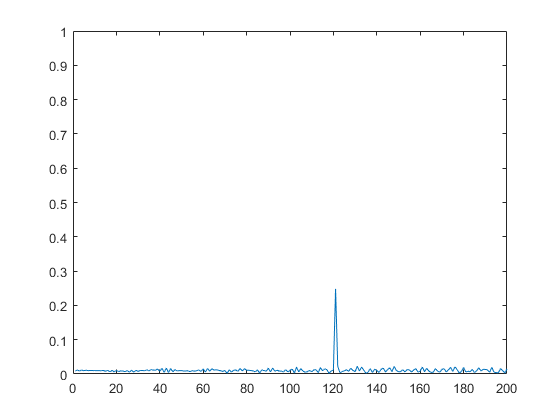

%% RANGE MEASUREMENT

 % *%TODO* :
%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
Mix=reshape(Mix,[Nr,Nd]);
 % *%TODO* :
%run the FFT on the beat signal along the range bins dimension (Nr) and
%normalize.
Mix_freq1 = fft(Mix, Nr)./Nr;
 % *%TODO* :
% Take the absolute value of FFT output
Mix_freq1 = abs(Mix_freq1);
 % *%TODO* :
% Output of FFT is double sided signal, but we are interested in only one side of the spectrum.
% Hence we throw out half of the samples.
Mix_freq = Mix_freq1(1:Nr/2);

%plotting the range
figure ('Name','Range from First FFT')
%subplot(2,1,1)

 % *%TODO* :
 % plot FFT output 
plot(Mix_freq);
axis ([0 200 0 1]);

### Range Doppler Map (RDM)

2D FFT output of sigle target.

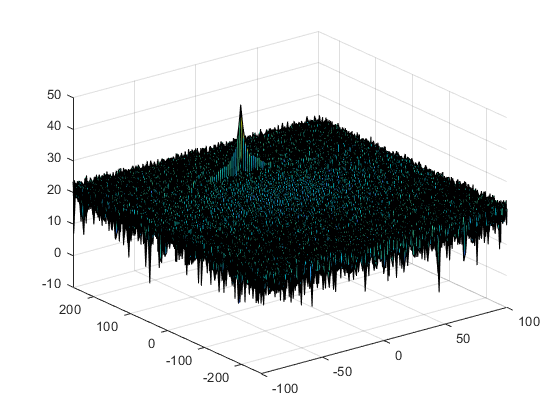

%% RANGE DOPPLER RESPONSE
% The 2D FFT implementation is already provided here. This will run a 2DFFT
% on the mixed signal (beat signal) output and generate a range doppler
% map.You will implement CFAR on the generated RDM


% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);

### **CFAR implementation**

Perform the CFAR processing on the output of 2nd FFT to display the target.

**2D CFAR Steps**

The following steps can be used to implement 2D-CFAR in MATLAB:

- Determine the number of Training cells for each dimension Tr and Td. Similarly, pick the number of guard cells Gr and Gd.

- Slide the Cell Under Test (CUT) across the complete cell matrix

- Select the grid that includes the training, guard and test cells. Grid Size = (2Tr+2Gr+1)(2Td+2Gd+1).

- The total number of cells in the guard region and cell under test. (2Gr+1)(2Gd+1).

- This gives the Training Cells : (2Tr+2Gr+1)(2Td+2Gd+1) - (2Gr+1)(2Gd+1)

- Measure and average the noise across all the training cells. This gives the threshold

- Add the offset (if in signal strength in dB) to the threshold to keep the false alarm to the minimum.

- Determine the signal level at the Cell Under Test.

- If the CUT signal level is greater than the Threshold, assign a value of 1, else equate it to zero.

- Since the cell under test are not located at the edges, due to the training cells occupying the edges, we suppress the edges to zero. Any cell value that is neither 1 nor a 0, assign it a zero.

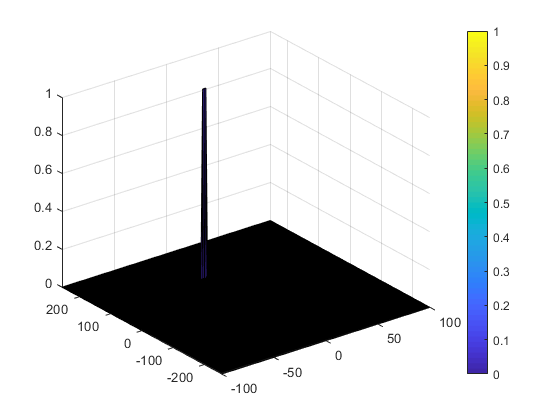

%% CFAR implementation

%Slide Window through the complete Range Doppler Map

% *%TODO* :
%Select the number of Training Cells in both the dimensions.
Tr = 10;
Td = 4;

% *%TODO* :
%Select the number of Guard Cells in both dimensions around the Cell under 
%test (CUT) for accurate estimation
Gr = 4;
Gd = 2;

Training_size = (2*Tr+2*Gr+1)*(2*Td+2*Gd+1)-(2*Gr+1)*(2*Gd+1);

% *%TODO* :
% offset the threshold by SNR value in dB
offset = 15;

% *%TODO* :
%design a loop such that it slides the CUT across range doppler map by
%giving margins at the edges for Training and Guard Cells.
%For every iteration sum the signal level within all the training
%cells. To sum convert the value from logarithmic to linear using db2pow
%function. Average the summed values for all of the training
%cells used. After averaging convert it back to logarithimic using pow2db.
%Further add the offset to it to determine the threshold. Next, compare the
%signal under CUT with this threshold. If the CUT level > threshold assign
%it a value of 1, else equate it to 0.


% Vector to hold threshold values 
threshold_cfar2D = zeros(size(RDM));
%Vector to hold final signal after thresholding
signal_cfar2D = zeros(size(RDM));

% Slide window across the both dimensions of the range doppler block
for i = Tr+Gr+1:(Nr/2-(Gr+Tr))
    for j = Td+Gd+1:(Nd-(Gd+Td)) 
        %Determine the noise threshold by measuring it within the training cells

        %Create a vector to store noise_level for each iteration on training cells
        noise_level = zeros(1,1);

        for m = i-(Tr+Gr):i+(Tr+Gr)
            for n = j-(Td+Gd):j+(Td+Gd)
                if(abs(i-m)>Gr || abs(j-n)>Gd)
                    noise_level = noise_level+db2pow(RDM(m,n));
                end
            end
        end
        threshold=pow2db(noise_level/Training_size)+offset;
        threshold_cfar2D(i,j) = threshold;
        %Filter the signal above the threshold
        if(RDM(i,j)> threshold)
            signal_cfar2D(i,j)=1;
        else
            signal_cfar2D(i,j) = 0;
        end
    end
end

figure,surf(doppler_axis,range_axis,signal_cfar2D);
colorbar;